% Define the size and initialize variables
n = 100;
p_vals = [10, 100, 1000, 2000];
lambda = 0.1;
time_p = zeros(1, length(p_vals));
time_n = zeros(1, length(p_vals));

% Main loop
for idx = 1:numel(p_vals)
    p = p_vals(idx);
    Identity_n = eye(n);
    Identity_p = eye(p);
    RandomMatrix = randi([1, 100], n, p);

    % Calculate B
    tic;
    B = (RandomMatrix' * RandomMatrix + lambda * Identity_p) \ RandomMatrix';
    time_p(idx) = toc;

    % Calculate C
    tic;
    C = RandomMatrix' / (RandomMatrix * RandomMatrix' + lambda * Identity_n);
    time_n(idx) = toc;
end

% Convert to milliseconds
time_p = time_p * 1000;
time_n = time_n * 1000;

% Display results
fprintf("t_p: ");

t_p: 

disp(time_p);

   29.7585    1.2663   48.6176  183.8293



fprintf("t_n: ");

t_n: 

disp(time_n);

    5.1527    0.5089    1.8675   33.9304



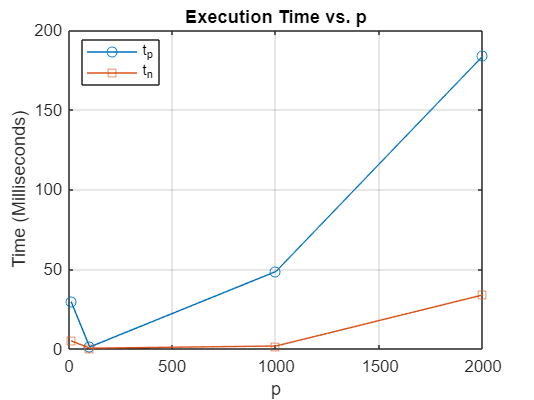


% Plotting
figure;
plot(p_vals, time_p, '-o', 'DisplayName', 't_p');
hold on;
plot(p_vals, time_n, '-s', 'DisplayName', 't_n');
xlabel('p');
ylabel('Time (Milliseconds)');
title('Execution Time vs. p');
legend('show', 'Location', 'Best');
grid on;
hold off;